# Angewandte Mathematik - Projekt Zeitaufgelöste Photolumineszenz

von Hakan Samet Yasar, s0558779

## 2. Finite Differenzen der stationären Gleichung

Aufgabenstellung: "Im ersten Schritt soll nur der in $u\;$lineare Anteil der Gleichung (4 vom Aufgabenblatt) ohne den quadratischen Term $-k_2 u^2$ untersucht werden: 

${{\textrm{Du}}^{\prime } }^{\prime } -\textrm{ku}-k_2 u^2 =-s\left(z\right),0<z<d,$  (1)

mit $k=k_1 +k_2 N_D$. Die Randbedingung sind weiterhin durch folgende Gleichung gegeben:

    $Du^{\prime } \left(0\right)=\textrm{SLu}\left(0\right),\;Du^{\prime } \left(d\right)=-\textrm{SRu}\left(d\right)$ (2) 

### 2.1 Lineare Stationäre Gleichung

#### 2.1.1 Vorgehen

Mithilfe der in [1] gegebenen Gleichungen (8.126 und 8.127) werden die gesuchten Variablen der  Gleichung (1) an den Randbedingungen approximiert.Daraufhin werden die Randbedingungen nach $u_{-1}$und $u_{N+1}$ umgeformt, daraus entstehen N+1 Gleichungen.

Hierbei werden die Gleichungen $i=0\;$und $i=N+1$ extra berechnet. Für die Gleichung $i=0$ wird die erste Ranbedingung und in die letzte Gleichung $i=N+1$ die zweite Randbedingung eingesetzt. Alle Gleichungen die danach übrig bleiben unterscheiden sich nur in ihrem Index.

Im letzten Schritt wird ein Lineares Gleichungssystem als Matrix nach $\textrm{Au}=b\;$aufgestellt.

#### 2.1.2 Herleitung der Gleichung

Gegeben:

${{\textrm{Du}}^{\prime } }^{\prime } -\textrm{ku}=-s\left(z\right)\;$(3) und die Formel für die zweite Ableitung aus [1] ${u^{\prime } }^{\prime } =\frac{u_{i+1} -2u_{i\;} +u_{i-1} }{h^2 }$ (4)

Rechnung:

Im Folgenden setzen wir die Gleichung (4) in (3) wie in [1] beschrieben.


$$\begin{array}{l}
D\cdot \frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-{\textrm{ku}}_i ={-s}_i \\
D\cdot \frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-{\textrm{ku}}_i ={-s}_i \;\left|:D\right.\\
\frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }-\frac{{\textrm{ku}}_i }{D}=\frac{{-s}_i }{D}\;\left|{\cdot h}^2 \right.\\
u_{i+1} -2u_i -\frac{{\textrm{ku}}_i \cdot h^2 }{D}+u_{i-1} =\frac{{-s}_i \cdot h^2 }{D}
\end{array}$$
 

$u_{i+1} -u_i \left(2+\frac{k\cdot h^2 }{D}\right)+u_{i-1} =\frac{{-s}_i \cdot h^2 }{D}$ (5)

#### 2.1.3 Approximierung an den Randbedingungen

Gegeben:

$D\cdot u^{\prime } \left(0\right)=S_L u\left(0\right)$(6)

$D\cdot u^{\prime } \left(d\right)=S_R u\left(d\right)$ (7)

Rechnung:

Im Folgenden werden die Ableitungen in den Randbedingungen durch $u^{\prime } \left(0\right)=\frac{u_1 -u_{-1} }{2h}$ und $u^{\prime } \left(d\right)=\frac{u_{N+1} -u_{N-1} }{2h}$ approximiert. 

$D\cdot \frac{u_1 -u_{-1} }{2h}=S_L u\left(0\right)\to u_{-1} =u_1 -\frac{S_L \cdot 2h}{D}u_0 \;\;$(6)

$D\cdot \frac{u_{N+1} -u_{N-1} }{2h}=S_R u\left(d\right)\to u_{N+1} =-\frac{S_R \cdot 2h}{D}\cdot u_N +u_{N-1}$ (7)

#### 2.4.1 Lineares Gleichungssystem

Nachdem die Ableitungen in den Randbedingungen (6) (7) approximiert wurden können diese in die Gleichung (5) für $i=0\;$ und $i=N$ eingesetzt werden.

Rechnung:

$u_{i+1} -u_i \left(2+\frac{k\cdot h^2 }{D}\right)+u_{i-1} =\frac{{-s}_i \cdot h^2 }{D}$  mit $i=0$


$$\begin{array}{l}
u_1 -u_0 \left(2+\frac{k\cdot h^2 }{D}\right)+u_{-1} =\frac{{-s}_i \cdot h^2 }{D}\\
u_1 -u_0 \left(2+\frac{k\cdot h^2 }{D}\right)+u_1 -\frac{S_L \cdot 2h}{D}u_0 =\frac{-s_0 \cdot h^2 }{D}\\
{2\mathit{\mathbf{u}}}_1 -{\mathit{\mathbf{u}}}_0 \left(2+\frac{\mathit{\mathbf{k}}\cdot {\mathit{\mathbf{h}}}^2 }{\mathit{\mathbf{D}}}-\frac{{\mathit{\mathbf{S}}}_{\mathit{\mathbf{L}}} \cdot 2\mathit{\mathbf{h}}}{\mathit{\mathbf{D}}}\right)=\frac{-{\mathit{\mathbf{s}}}_0 \cdot {\mathit{\mathbf{h}}}^2 }{\mathit{\mathbf{D}}}
\end{array}$$


$u_{i+1} -u_i \left(2+\frac{k\cdot h^2 }{D}\right)+u_{i-1} =\frac{{-s}_i \cdot h^2 }{D}$  mit $i=N$


$$\begin{array}{l}
u_{N+1} -u_N \left(2+\frac{k\cdot h^2 }{D}\right)+u_{N-1} =\frac{-S_N \cdot h^2 }{D}\\
\frac{S_R \cdot 2h}{D}\cdot u_N +u_{N-1} -u_N \left(2+\frac{k\cdot h^2 }{D}\right)+u_{N-1} =\frac{-S_N \cdot h^2 }{D}\\
2{\mathit{\mathbf{u}}}_{\mathit{\mathbf{N}}-1} -{\mathit{\mathbf{u}}}_{\mathit{\mathbf{N}}} \left(2+\frac{\mathit{\mathbf{k}}\cdot {\mathit{\mathbf{h}}}^2 }{\mathit{\mathbf{D}}}-\frac{{\mathit{\mathbf{S}}}_{\mathit{\mathbf{R}}} \cdot 2\mathit{\mathbf{h}}}{\mathit{\mathbf{D}}}\right)=-\frac{{\mathit{\mathbf{S}}}_{\mathit{\mathbf{N}}} \cdot {\mathit{\mathbf{h}}}^2 }{\mathit{\mathbf{D}}}
\end{array}$$


Im Folgenden werden wir ein mittleren Index der Matrix demonstrativ von berechnet.

Gebeben:


$$u_{i+1} -u_i \left(2+\frac{k\cdot h^2 }{D}\right)+u_{i-1} =\frac{{-s}_i \cdot h^2 }{D}$$
 

Rechnung:


$$i=1\to u_{2\;} -u_1 \left(2+\frac{h^2 k}{D}\right)+u_0 =\frac{-S_1 h^2 }{D}$$


Jetzt sind wir in der Lage unser Lineares Gleichungsystem in Form von $\textrm{Au}=b$ aufzustellen.


$$\left\lbrack \begin{array}{ccccc}
-\left(2+\frac{\mathit{\mathbf{k}}\cdot {\mathit{\mathbf{h}}}^2 }{\mathit{\mathbf{D}}}-\frac{{\mathit{\mathbf{S}}}_{\mathit{\mathbf{L}}} \cdot 2\mathit{\mathbf{h}}}{\mathit{\mathbf{D}}}\right) & 2 & 0 & 0 & 0\\
1 & -\left(2+\frac{h^2 k}{D}\right) & 1 & 0 & 0\\
0 & 1 & -\left(2+\frac{h^2 k}{D}\right) & 1 & 0\\
0 & 0 & 1 & -\left(2+\frac{h^2 k}{D}\right) & 0\\
0 & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
0 & 0 & 0 & 2 & -\left(2+\frac{\mathit{\mathbf{k}}\cdot {\mathit{\mathbf{h}}}^2 }{\mathit{\mathbf{D}}}-\frac{{\mathit{\mathbf{S}}}_{\mathit{\mathbf{R}}} \cdot 2\mathit{\mathbf{h}}}{\mathit{\mathbf{D}}}\;\right)
\end{array}\right\rbrack \;\;\;\cdot \;\;\left\lbrack \begin{array}{c}
u_0 \\
u_1 \\
u_2 \\
u_3 \\
\ldotp \ldotp \ldotp \\
u_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{-S_0 h^2 }{D}\\
\frac{-S_1 h^2 }{D}\\
\frac{-S_2 h^2 }{D}\\
\frac{-S_3 h^2 }{D}\\
\ldotp \ldotp \ldotp \\
\frac{-S_N h^2 }{D}
\end{array}\right\rbrack \;\;\;\;$$


#### 2.1.5 Routine fd_lin_matrix

Die Routine wurde erfolgreich implentiert.

A = fd_lin_matrix(3);
full(A)

ans =    -2.4333    2.0000         0         0
    1.0000   -2.3667    1.0000         0
         0    1.0000   -2.3667    1.0000
         0         0    2.0000 -669.0333


#### 2.1.6 Routine stationaer_lin

Zur Lösung der aufgestellten Matrix wurde eine Routine implementiert. Als Eingabe wird ein Funktionhandler **s **(siehe s.m) und die Anzahl der Teilintervale übergeben.

#### 2.1.7 Test der Routine

Im Folgenden wird eine Testroutine zum testen der Routine **stationaer_lin** erstellt. Hierfür wird eine $u\left(z\right)$und die Konstanten $d,D,k$ festgelegt und geprüft, inwiefern diese sich der von unserer Routine berechnet werten nährt.

Gegeben:


$$\begin{array}{l}
u\left(z\right)=z^3 +2z^2 +5z+8\\
d=0,4=\frac{2}{5}\\
D=0,6=\frac{3}{5}\\
k=2
\end{array}$$


Nachdem die Werte festgelegt wurden kann nun $s\left(z\right)\;$zusammen mit $S_L$und $S_R$ berechnet werden. Dafür muss zuerst die erste und zweite Ableitung von $u\left(z\right)$ gebildet werden.


$$u^{\prime } \left(z\right)=3z^2 \;+4z+5,\;{u^{\prime } }^{\prime } \left(z\right)=6z+4$$


Rechnung:

Zur Berechnung von $s\left(z\right)$setzen wir die Ableitungen in die Funktion ein.


$$\begin{array}{l}
D\cdot {u^{\prime } }^{\prime } -\textrm{ku}=-s\left(z\right)\\
\frac{3}{5}\cdot \left(6z+4\right)-2\left(z^3 +2z^2 +5z+8\right)=-s\left(z\right)\\
-2z^3 -4z^2 -\frac{32}{5}z-\frac{68}{5}=-s\left(z\right)\\
2z^3 +4z^2 +\frac{32}{5}z+\frac{68}{5}=s\left(z\right)
\end{array}$$


Für die Berechnung der Randbedingungen setzen wir ebenfalls die Ableitungen in die gegeben Funktionen ein.


$$\begin{array}{l}
D\cdot u^{\prime } \left(0\right)=S_L u\left(0\right)\\
\frac{3}{5}\left(3z^2 +4z+5\right)=S_L \left(z^3 +2z^2 +5z+8\right)\\
\frac{3}{5}\left(3{\cdot \;0}^2 +4\cdot 0+5\right)=S_L \left(0^3 +2{\cdot \;0}^2 +5\cdot 0+8\right)\\
\frac{3}{8}=S_L 
\end{array}$$



$$\begin{array}{l}
D\cdot u^{\prime } \left(d\right)=-S_R u\left(d\right)\\
\frac{3}{5}\left({3\cdot \left(\frac{2}{5}\right)}^2 +\frac{8}{5}+5\right)=-S_R \cdot \left({\frac{2}{5}}^3 +2\cdot {\left(\frac{2}{5}\right)}^2 +5\cdot \left(\frac{2}{5}\right)+8\right)\\
\frac{3}{5}\left(\frac{177}{25}\right)=-S_R \cdot \left(\frac{1298}{125}\right)\\
-\frac{9}{22}=S_{R\;} 
\end{array}$$


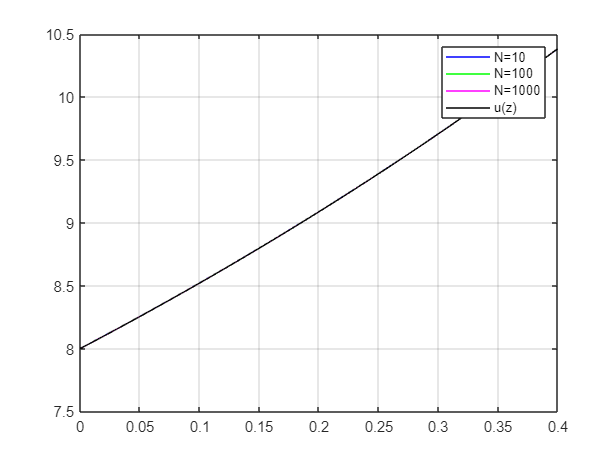

test_routine_stat_lin

#### 2.1.8 Berechnung von s0 und Raten von N

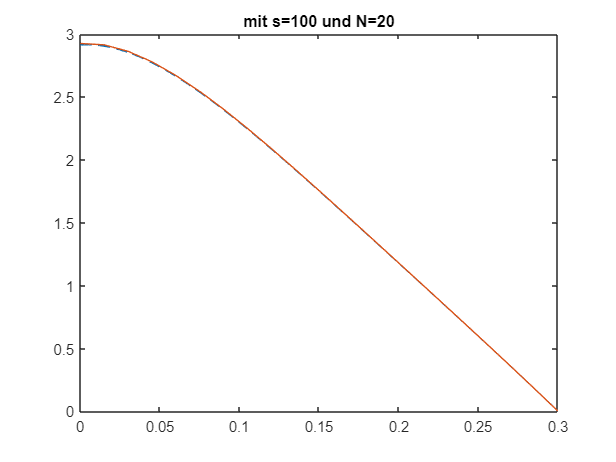

[relFehler] = rel_Fehler(1e2,20,"lin");

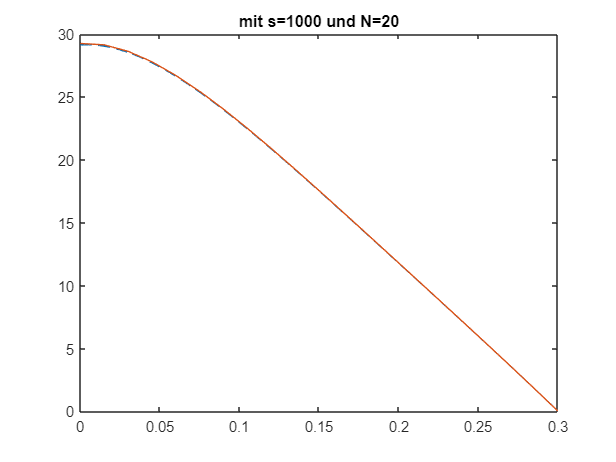

relFehler = 0.0042

[relFehler] = rel_Fehler(1e3,20,"lin")

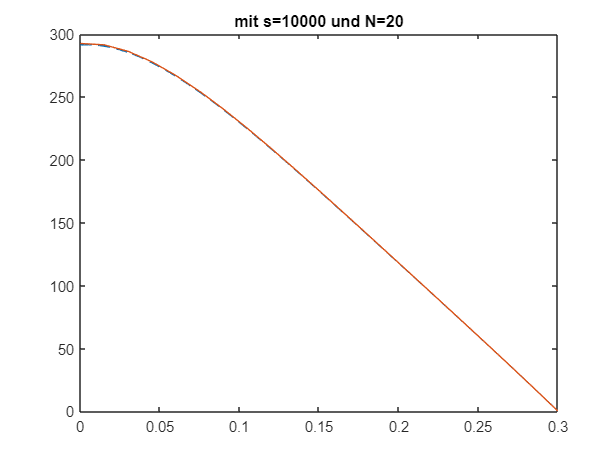

relFehler = 0.0042

[relFehler] = rel_Fehler(1e4,20,"lin")

### 2.2 Nichtlineare stationäre Gleichung

Im Folgenden werden wir die Gleichung (1) samt Ihrem nicht linearen Teil $k_2 u^{2\;}$lösen. Hierfür muss die Gleichung mit Ihren Unbekannten $u_0 ,u_1 ,\ldotp \ldotp \ldotp \ldotp u_N$hergeleitet und in der Form $F\left(u\right)=b$ dargestellt werden.

#### 2.2.1 Herleitung der Gleichung

Gegegeben:

${{\textrm{Du}}^{\prime } }^{\prime } -\textrm{ku}-k_2 u^2 =-s\left(z\right)$ mit $k=k_1 +k_2 \cdot N_D$ (1)

$D\cdot u^{\prime } \left(0\right)=S_L u\left(0\right),D\cdot u^{\prime } \left(d\right)={-S}_R u\left(d\right)\;$(Randbedingung) (2)

${u^{\prime } }^{\prime } =\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }$ (4) (Approximation aus [1])

Rechnung:

Zur Herleitung der gesuchten Gleichung, wird in (1) die Approximation (4) eingesetzt wie in Aufgabe 2.1.*  


$$\begin{array}{l}
\left(D\cdot \left(\frac{u_{i+1} -2\cdot u_i +u_{i-1} }{h^2 }\right)\right)-\textrm{ku}-k_2 u^2 =-s\left(z\right)\left|:D\;\right|\cdot h^2 \\
u_{i+1} -2u_i +u_{i-1} -\;\frac{\;{\textrm{ku}}_i h^2 }{D}-\frac{k_2 u_i^2 h^2 }{D}=-\frac{s_i h^2 }{D}\;\left(5\ldotp 1\right)
\end{array}$$


Im Folgenden werden die Ableitungen in den Randbedingungen durch $u^{\prime } \left(0\right)=\frac{u_1 -u_{-1} }{2h}$ und $u^{\prime } \left(d\right)=\frac{u_{N+1} -u_{N-1} }{2h}$ approximiert. 

$D\cdot \frac{u_1 -u_{-1} }{2h}=S_L u\left(0\right)\to u_{-1} =u_1 -\frac{S_L \cdot 2h}{D}u_0 \;\;$(6)

$D\cdot \frac{u_{N+1} -u_{N-1} }{2h}=S_R u\left(d\right)\to u_{N+1} =-\frac{S_R \cdot 2h}{D}\cdot u_N +u_{N-1}$ (7)

Insofern die Randbedingungen approximiert sind, können diese nun in die Gleichung (5.1) für $i=0$ und  $i=N$eingesetzt werden.

$u_{i+1} -2u_i +u_{i-1} -\;\frac{\;{\textrm{ku}}_i h^2 }{D}-\frac{k_2 u_i^2 h^2 }{D}=-\frac{s_i h^2 }{D}$ mit $i=0$


$$\begin{array}{l}
u_1 -2u_0 +u_{-1} -\frac{{\textrm{ku}}_0 h^2 }{D}-\frac{k_2 u_0^2 h^2 }{D}=-\frac{s_i h^2 }{D}\\
u_1 -2u_0 +\left(u_1 -\frac{S_L 2h}{D}u_0 \right)-\frac{{\textrm{ku}}_0 h^2 }{D}-\frac{k_2 u_0^2 h^2 }{D}=-\frac{s_0 h^2 }{D}\\
u_1 -2u_0 +\left(u_1 -\frac{S_L 2h}{D}u_0 \right)-u_0 \frac{kh^2 }{D}-u_0^2 \frac{k_2 h^2 }{D}=-\frac{s_0 h^2 }{D}\\
2u_1 +u_0 \left(-2-\frac{S_L 2h}{D}-\frac{{\textrm{kh}}^2 }{D}\right)-u_0^2 \left(\frac{k_2 h^2 }{D}\right)=-\frac{s_0 h^2 }{D}
\end{array}$$


$u_{i+1} -2u_i +u_{i-1} -\;\frac{\;{\textrm{ku}}_i h^2 }{D}-\frac{k_2 u_i^2 h^2 }{D}=-\frac{s_i h^2 }{D}$ mit $i=N$

 
$$\begin{array}{l}
u_{N+1} -2u_N +u_{N-1} -\frac{{\textrm{ku}}_N h^2 }{D}-\frac{k_2 u_N^2 h^2 }{D}=-\frac{s_N h^2 }{D}\\
2u_{N-1} +u_N \left(-2-\frac{S_R 2h}{D}-\frac{{\textrm{kh}}^2 }{D}\right)-u_N^2 \frac{k^2 h^2 }{D}=-\frac{s_N h^2 }{D}
\end{array}$$


Nun können wir die Gleichung $F\left(u\right)=b$ aufstellen:


$$\left\lbrack \begin{array}{c}
2u_1 +u_0 \left(-2-\frac{S_L 2h}{D}-\frac{{\textrm{kh}}^2 }{D}\right)-u_0^2 \left(\frac{k_2 h^2 }{D}\right)\\
u_2 -2u_1 +u_0 -u_1 \left(\frac{{\textrm{kh}}^2 }{D}\right)-u_1^2 \left(\frac{k_2 h^2 }{D}\right)\\
u_3 -2u_2 +u_1 -u_2 \left(\frac{{\textrm{kh}}^2 }{D}\right)-u_2^2 \left(\frac{k_2 h^2 }{D}\right)\\
\ldotp \ldotp \ldotp \ldotp \\
2u_{N-1} +u_N \left(-2-\frac{S_R 2h}{D}-\frac{{\textrm{kh}}^2 }{D}\right)-u_N^2 \frac{k_2 h^2 }{D}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{s_0 h^2 }{D}\\
-\frac{s_1 h^2 }{D}\\
-\frac{s_2 h^2 }{D}\\
\ldotp \ldotp \ldotp \ldotp \\
-\frac{s_N h^2 }{D}
\end{array}\right\rbrack$$


#### 2.2.2 Routine fd_nonlin

Wie in der Aufgabenbeschreibung beschrieben wurde die soeben erstellte Gleichung über die fd_nonlin realisert.

#### 2.2.3 Jacobi-Matrix

In diesem Abschnitt der Ausarbeitung wird die Jacobi Matrix der Matrix $A$aus der Aufgabe 2.4.1.. Die Jacobi Matrix wir durch das Ableiten jeder einzelnen Zeile gebildet.


$$\left\lbrack \begin{array}{ccccc}
\left(-2-\frac{S_L \cdot 2h}{D}-\frac{kh^2 }{D}\right)-2\cdot u_0 \left(\frac{k_2 \cdot h^2 }{D}\right) & 2 & 0 & 0 & 0\\
1 & \left(-2-\frac{kh^2 }{D}\right)-2{\cdot u}_1 \left(\frac{k_2 \cdot h^2 }{D}\right) & 1 & 0 & 0\\
0 & 1 & \left(-2-\frac{kh^2 }{D}\right)-2{\cdot u}_2 \left(\frac{k_2 \cdot h^2 }{D}\right) & 1 & 0\\
0 & 0 & 1 & \left(-2-\frac{kh^2 }{D}\right)-2u_3 \left(\frac{k_2 \cdot h^2 }{D}\right) & 1\\
0 & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
0 & 0 & 0 & 2 & \left(-2-\frac{h^2 k}{D}-\frac{S_R \cdot 2h}{D}\right)-{2u}_N \left(\frac{k_2 \cdot h^2 }{D}\right)
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
u_0 \\
u_1 \\
u_2 \\
u_3 \\
\ldotp \ldotp \ldotp \\
u_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{-S_0 h^2 }{D}\\
\frac{-S_1 h^2 }{D}\\
\frac{-S_2 h^2 }{D}\\
\frac{-S_3 h^2 }{D}\\
\ldotp \ldotp \ldotp \\
\frac{-S_N h^2 }{D}
\end{array}\right\rbrack$$


#### 2.2.4 fd_nonlin_jac

Die Routine wurde implementiert und kann im Folgenden für das erstellen der Jacobi Matrix aufgestellt werden

u=(1:11)';
J=fd_nonlin_jac(u,10);
full(J)

ans =    -2.0531    2.0000         0         0         0         0         0         0         0         0         0
    1.0000   -2.0331    1.0000         0         0         0         0         0         0         0         0
         0    1.0000   -2.0332    1.0000         0         0         0         0         0         0         0
         0         0    1.0000   -2.0332    1.0000         0         0         0         0         0         0
         0         0         0    1.0000   -2.0333    1.0000         0         0         0         0         0
         0         0         0         0    1.0000   -2.0334    1.0000         0         0         0         0
         0         0         0         0         0    1.0000   -2.0334    1.0000         0         0         0
         0         0         0         0         0         0    1.0000   -2.0335    1.0000         0         0
         0         0         0         0         0         0         0    1.0000   -2.0335    1.0000      

#### 2.2.5 stationaer_nonlin

Im Folgenden wird die mithilfe des Newton-Verfahrens implementierte Routine ausgeführt.

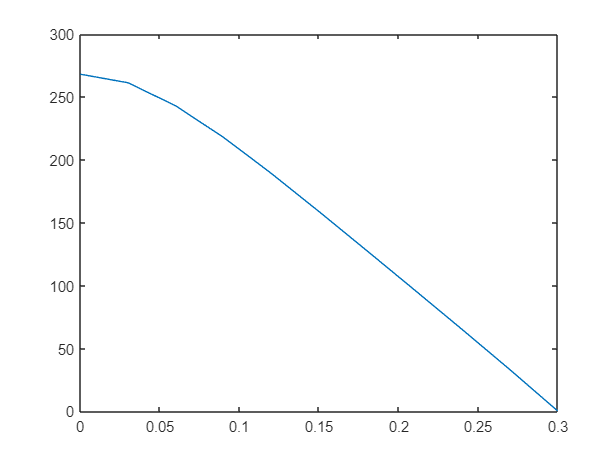

N=10;
tol = 1e-6;
nmax=20;
[z,u] = stationaer_nonlin(@s,N,tol,nmax);
plot(z,u)

#### 2.2.6 Test der Routine stationaer_nonlin

Im Folgenden wird eine Testroutine zum testen der Routine **stationaer_nonlin** erstellt. Hierfür wird eine $u\left(z\right)$und die Konstanten $d,D,k$ festgelegt und geprüft, inwiefern diese sich der von unserer Routine berechnet werten nährt.

Gegeben:


$$\begin{array}{l}
u\left(z\right)=z^3 +2z^2 +5z+8\\
d=0,4=\frac{2}{5}\\
D=0,6=\frac{3}{5}\\
k=2\\
k_2 =\frac{5}{2}
\end{array}$$


Nachdem die Werte festgelegt wurden kann nun $s\left(z\right)\;$zusammen mit $S_L$und $S_R$ berechnet werden. Dafür muss zuerst die erste und zweite Ableitung von $u\left(z\right)$ gebildet werden.


$$u^{\prime } \left(z\right)=3z^2 \;+4z+5,\;{u^{\prime } }^{\prime } \left(z\right)=6z+4$$


Rechnung:

Zur Berechnung von $s\left(z\right)$setzen wir die Ableitungen in die Funktion ein.


$$\begin{array}{l}
{{D\cdot u}^{\prime } }^{\prime } -k\cdot u-k_2 {\cdot u}^2 =-s\left(z\right)\\
D\cdot \left(6z+4\right)-k\cdot \left(z^3 +2z^2 +5z+8\right)-k_2 \cdot {\left(z^3 +2z^2 +5z+8\right)}^2 =-s\left(z\right)\\
\frac{3}{5}\cdot \left(6z+4\right)-2\cdot \left(z^3 +2z^2 +5z+8\right)-\frac{5}{2}\cdot {\left(z^3 +2z^2 +5z+8\right)}^2 =-s\left(z\right)\\
s\left(z\right)=-\frac{3}{5}\cdot \left(6z+4\right)+2\cdot \left(z^3 +2z^2 +5z+8\right)+\frac{5}{2}\cdot {\left(z^3 +2z^2 +5z+8\right)}^2 
\end{array}$$


Für die Berechnung der Randbedingungen setzen wir ebenfalls die Ableitungen in die gegeben Funktionen ein.


$$\begin{array}{l}
D\cdot u^{\prime } \left(0\right)=S_L u\left(0\right)\\
\frac{3}{5}\left(3z^2 +4z+5\right)=S_L \left(z^3 +2z^2 +5z+8\right)\\
\frac{3}{5}\left(3{\cdot \;0}^2 +4\cdot 0+5\right)=S_L \left(0^3 +2{\cdot \;0}^2 +5\cdot 0+8\right)\\
\frac{3}{8}=S_L 
\end{array}$$



$$\begin{array}{l}
D\cdot u^{\prime } \left(d\right)=-S_R u\left(d\right)\\
\frac{3}{5}\left({3\cdot \left(\frac{2}{5}\right)}^2 +\frac{8}{5}+5\right)=-S_R \cdot \left({\frac{2}{5}}^3 +2\cdot {\left(\frac{2}{5}\right)}^2 +5\cdot \left(\frac{2}{5}\right)+8\right)\\
\frac{3}{5}\left(\frac{177}{25}\right)=-S_R \cdot \left(\frac{1298}{125}\right)\\
-\frac{9}{22}=S_{R\;} 
\end{array}$$


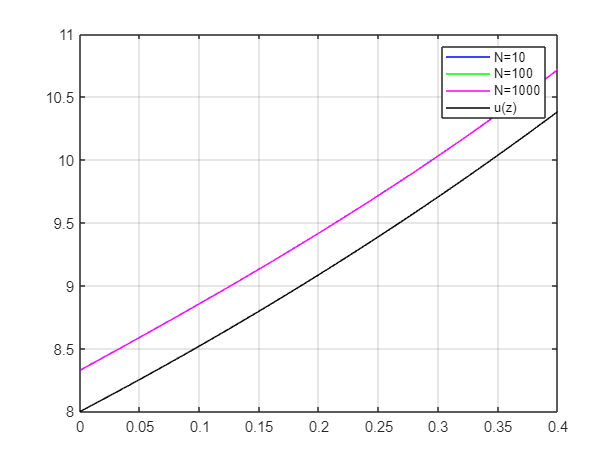

test_routine_stat_nonlin

#### 2.2.7 Berechnung von s0 und Raten von N

In diesem Abschnitt wird genauso vorgegangen wie in Abschnitt 2.1.8. und für je verschiedene S0 von 10-1000 ausgerechnet.

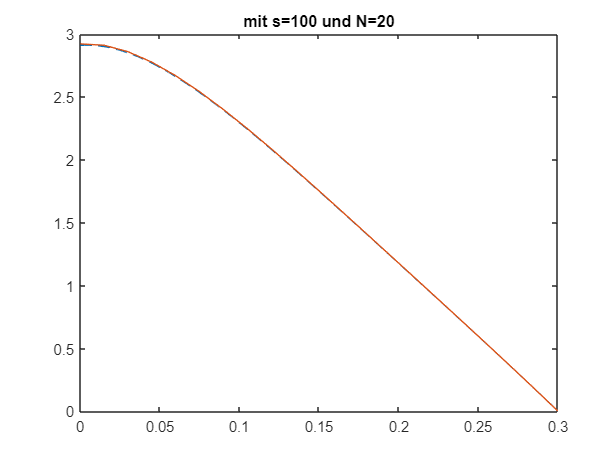

relFehler = 0.0042

[relFehler] = rel_Fehler(1e2,20,"nonlin")

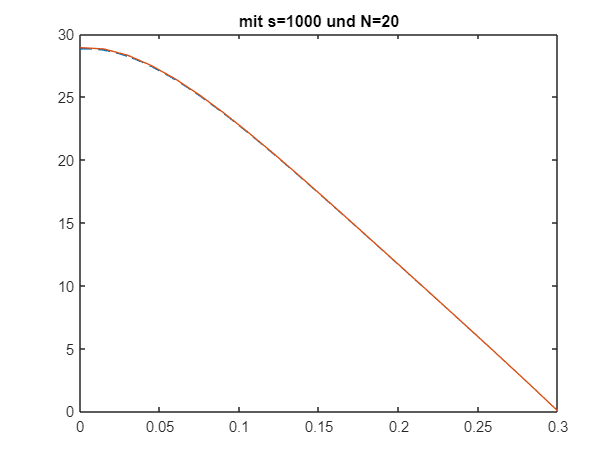

relFehler = 0.0042

[relFehler] = rel_Fehler(1e3,20,"nonlin")

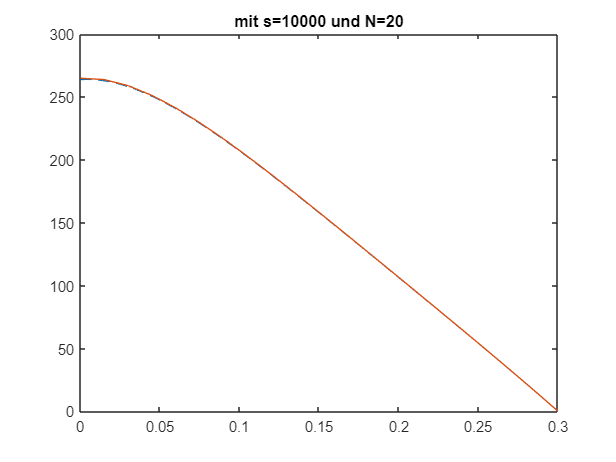

relFehler = 0.0041

[relFehler] = rel_Fehler(1e4,20,"nonlin")

Beim Betrachten der Graphen merkt man das meine Lösung u bei der Routine **stationaer_nonlin **kleiner als die im** stationaer_lin **ist. Besonders auffälig ist das bei $S_0 ={10}^{4\;} \;\textrm{und}\;N=20$.

## 3. Implizite Einschrittverfahren

Aufgabenstellung: In diesem Abschnitt sollen Löser für Systeme von sogenannten steifen Anfangswertproblemen untersucht werden. In Abschnitt 4 wird die partielle Differenzialgleichung (1 vom Aufgabenblatt) mithilfe der finiten Differenzen des letzten Abschnitts näherungsweise als ein System von Anfangswertproblemen formuliert, das sich steif verhält.

### 3.1. Entwicklung

#### 3.1.1  Steife Differentialgleichungen

Bei steifen Differentialgleichungen handelt es sich um Typen von Systemen, wo bestimmte Komponenten schnell und andere sich langsam verhalten können. In diesem Fall sind die uns bereits bekannten expliziten Verfahren wie das Euler-Verfahren nur sehr schwer darauf anwendbar. Um ein genaures Ergebnis mit expliziten Verfahren erreichen zu können muss die Schrittweite der Lösung so klein gewählt werden, um eine ausreichend gute Approximation für alle Komponenten im System zu erreichen.Dies hat zur Folge, dass dadurch ein höherer Rechenaufwand entsteht und das Verfahren innefizient arbeitet.

Im Allgemeinen gilt, dass steife Differentialgleichungen  die Differentialgleichungen sind, die effizienter mit einem Impliziten Verfahren gelöst werden können. Sie ermöglichen es uns mit größeren Schrittweiten und der daraus resultierende geringere Rechenaufwand bessere nummerische Lösungen zu erzielen.

#### 3.1.2 Formulierung der Gleichungen für das implizite Euler-Verfahren und der impliziten Trapezregel

Im Folgenden Abschnitt der Ausarbeitung werden die Gleichungen der impliziten Verfahren als Nullstellenprobleme dargestellt. Zuerst wird die Gleichung des impliziten Euler-Verfahrens umgeformt und im Anschluss die der Trapezregel.

**Eulerverfahren:**

Gegeben: 

$y^{\left(i+1\right)} =y^{\left(i\right)} +h\cdot f\left(t_{i+1} ,y^{\left(i+1\right)} \right)\;\textrm{und}\;y^{\left(i+1\right)} =y^{\left(i\right)} +z$ aus der Aufgabenstellung, in der Ausarbeitungen sind die Indizes wie in der Vorlesung, bei mir auch, unten.

Rechnug:

Wie in der Aufgabenstellung beschrieben, wird  $y^{\left(i+1\right)} =y^{\left(i\right)} +z$ in die Gleichung des impliziten Euler-Verfahrens eingesetzt.


$$\begin{array}{l}
y_i +z=y_i +h\cdot f\left(t_{i+1} ,y_i +z\right)\;\left|-y_i \;\right|-z\\
0=-z+h\cdot f\left(t_{i+1} ,y_i +z\right)
\end{array}$$


Nun erhalten wir ein Nullstellenproblem mit der unbekannten $z$. Hieraus ergibt sich unser $F_{\textrm{Euler}\;} \left(z\right)=0$


$$F_{\textrm{Euler}\;} \left(z\right)=$$
 
$$-z+h\cdot f\left(t_{i+1} ,y_i +z\right)$$


Abgeleitet nach z sieht es wie folgt aus:


$${F^{\prime } }_{\textrm{Euler}\;} \left(\textrm{sz}\right)=$$
 
$$-1+h\cdot \textrm{df}\left(t_{i+1} ,y_i +z\right)$$


**Trapezregel:**

Gegeben:

$y^{\left(i+1\right)} =y^{\left(i\right)} +\frac{h}{2}\left\lbrack f\left(t_i ,y^{\left(i\right)} \right)+f\left(t_{i+1} ,y^{\left(i+1\right)} \right)\right\rbrack \;\textrm{und}\;y^{\left(i+1\right)} =y^{\left(i\right)} +z$ aus der Aufgabenstellung, in der Ausarbeitungen sind die Indizes wie in der Vorlesung, bei mir auch, unten.


$$\begin{array}{l}
y_i +z=y_i +\frac{h}{2}\left\lbrack f\left(t_i ,y_i \right)+f\left(t_{i+1} ,y_i +z\right)\right\rbrack \;\;\left|-y_{i\;\;} \right|-z\\
0=-z+\frac{h}{2}\left\lbrack f\left(t_i ,y_i \right)+f\left(t_{i+1} ,y_i +z\right)\right\rbrack 
\end{array}$$


Nun erhalten wir ein Nullstellenproblem mit der unbekannten $z$. Hieraus ergibt sich unser $F_{\textrm{Trapez}\;} \left(z\right)=0$


$$F_{\textrm{Trapez}\;} \left(z\right)=$$
 
$$-z+\frac{h}{2}\left\lbrack f\left(t_i ,y_i \right)+f\left(t_{i+1} ,y_i +z\right)\right\rbrack$$


Abgeleitet nach z sieht es wie folgt aus:


$${F^{\prime } }_{\textrm{Trapez}\;} \left(z\right)=$$
 
$$-1+\frac{h}{2}\left\lbrack f\left(t_{i+1} ,y_i +z\right)\right\rbrack$$


#### 3.1.3 Jacobi Matrix für F_Euler und F_Trapez

Für die soeben erstellten Gleichungen wird die Jacobi Matrix für $F_{\textrm{Euler}} \;\textrm{und}\;F_{\textrm{Trapez}}$ in Abhängigkeit von $D_y f$erstellt.


$${F^{\prime } }_{\textrm{Euler}\;} \left(z\right)=$$
 
$$-1+h\cdot \textrm{df}\left(t_{i+1} ,y_i +z\right)$$



$${F^{\prime } }_{\textrm{Trapez}\;} \left(z\right)=$$
 
$$-1+\frac{h}{2}\left\lbrack f\left(t_{i+1} ,y_i +z\right)\right\rbrack$$



$$D_y f=\left\lbrack \begin{array}{cccc}
F_1^{\prime } \left(z_1 \right) & F_1^{\prime } \left(z_2 \right) & \ldotp \ldotp \ldotp  & F_1^{\prime } \left(z_n \right)\\
F_2^{\prime } \left(z_1 \right) & F_2^{\prime } \left(z_2 \right) & \ldotp \ldotp \ldotp  & F_2^{\prime } \left(z_n \right)\\
\vdots  & \vdots  & \; & \vdots \\
F_m^{\prime } \left(z_1 \right) & F_m^{\prime } \left(z_2 \right) & \ldotp \ldotp \ldotp  & F_m^{\prime } \left(z_n \right)
\end{array}\right\rbrack$$


für die Ableitung von -z wird die Einheitsmatrix $\textrm{dz}$ erstellt.


$$\textrm{dz}=\left\lbrack \begin{array}{cccc}
1 & 0 & \cdots  & 0\\
0 & 1 & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & 0\\
0 & \cdots  & 0 & 1
\end{array}\right\rbrack$$


#### 3.1.4 Routine F_Euler und F_Trapez

Die Routinen F_Euler und F_Trapez wurden erfolgreich implementiert und kann im Nachfolgenden Schritt  als Funktionshandle des Newton Verfahrens für die Routinen impl_euler() und impl_trapez verwendet werden.

#### 3.1.5 Routine impl_euler und impl_trapez

Die Routine impl_euler und impl_trapez wurden erfolgreich mit dem Newton-Verfahren implementiert. Die Richtigkeit der Verfahren wurden mit dem Anfangswertproblem aus der Aufgabe 3.1.6 mit ode45 getestet.

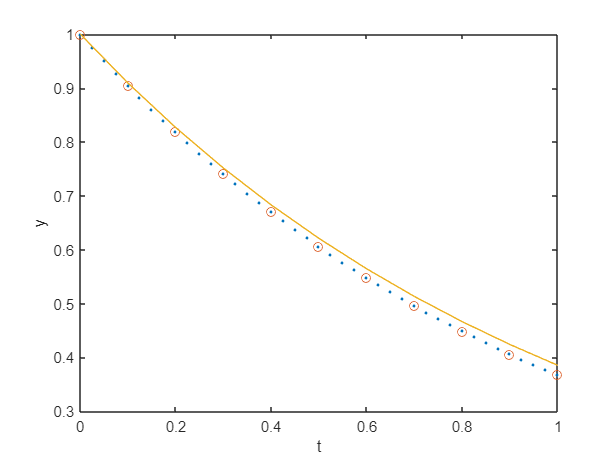

f=@(t,y)-y;
df=@(t,y)-1;
ya=1;
tspan = [0,1];
tol = 10e-6;
n=10;
nmax=100;

[tEuler,yEuler]=impl_euler(f,tspan,ya,n, df, tol, nmax);
[tTrapez,yTrapez]=impl_trapez(f,tspan,ya,n, df, tol, nmax);
[tOde,yOde]=ode45(f,tspan,ya);

plot(tOde,yOde,'.',tTrapez,yTrapez,'o',tEuler,yEuler);
xlabel('t');
ylabel('y');

#### 3.1.6 Ordnung 

 In diesem Aufgabenteil soll für das Anfangswertproblem die Ordnung ,der absoluten Fehler, für die implementierten Verfahren impl_euler() und impl_trapez() graphisch dargestellt werden. Für diesen Teilabschnitt vewenden wir die Formel des absoluten Fehlers aus dem Ubungsblatt 8 – Skalare Differenzialgleichungen 1. Ordnung, Aufgabe 8.2 c) und ihre Aufzeichnungen zur Vorlesung aus dem dem 30.01.2021.

Gegeben:

AWP: $y^{\prime } =-y$ mit Anfangsbedingung $y\left(0\right)=1$ auf dem Interval t=[0,1]

Lösung des des AWP aus Wolfram alpha $y\left(x\right)=c_1 \cdot e^{-x}$

Rechnung:

%Funktion,Ableitung und Lösung
f =@(t,y)-y;
df =@(t,y)-1;
dfEquSol =@(x)exp(-x);

%Benötigte Bedingungen
ya = 1;
tspan = [0,1];
tol = 10e-6;
n = 10.^(1:5); 
nmax = 100;

absFehlerEuler = max_abs_fehler(@(n) impl_euler(f,tspan,ya,n,df,tol,nmax),dfEquSol,n)

absFehlerEuler =     0.0177
    0.0018
    0.0002
    0.0000
    0.0000


absFehlerTrapez = max_abs_fehler(@(n) impl_trapez(f,tspan,ya,n,df,tol,nmax),dfEquSol,n)

absFehlerTrapez = 	1.0e+-3 *

    0.3069
    0.0031
    0.0000
    0.0000
    0.0000


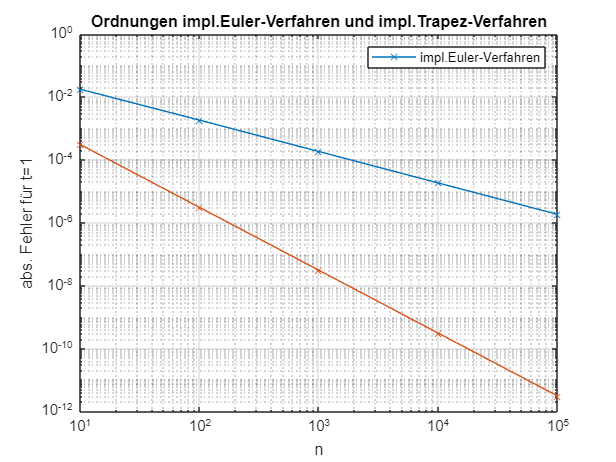


loglog(n,absFehlerEuler,'x-','DisplayName','impl.Euler-Verfahren');
title('Ordnungen impl.Euler-Verfahren und impl.Trapez-Verfahren')
xlabel("n");
ylabel('abs. Fehler für t=1')
legend show
grid on;
hold on;
loglog(n,absFehlerTrapez,'x-','DisplayName','impl.Trapez-Verfahren');
hold off;

In der Grafik ist zu erkennen, dass die die impl. Trapezregel einen geringeren absoluten Fehler als das Euler-Verfahren  bis  $n={10}^5 \;$hat. 

#### 3.1.7 Test der Routine 

Für das Testsysytem habe ich mir ein nichtlineares Gleichungssystem ausgedacht:


$$y^{\prime } =\left\lbrack \begin{array}{c}
-2t\cdot y_1 -3y_2 \\
2y_1 +{t^2 \cdot \;y}_2 
\end{array}\right\rbrack \;\textrm{mit}\;y\left(0\right)=\left\lbrack \begin{array}{c}
3\\
1
\end{array}\right\rbrack ,t=\left\lbrack 0,2\right\rbrack ,$$


Um die Richtigkeit meiner Verfahren zu prüfen wird die Methode ode45 verwendet und geprüft, on die Verfahren mit dem selben Gleichungssytem ähnliche Grafiken haben.

n = 10^2;
ya =[3;1];
tspan = [0,2];
tol = 10e-6;
nmax=100;

f_rb = @(t,y)[-2*t*y(1)-3*y(2);2*y(1)+t.^2*y(2)];

syms y1 y2 t
JacobiMatrix_fr_b = jacobian([-2*t*y1-3*y2;2*y1+t.^2*y2], [y1,y2])  

$$JacobiMatrix\_fr\_b = \left(\begin{array}{cc} -2\,t & -3\\ 2 & t^{2} \end{array}\right)$$

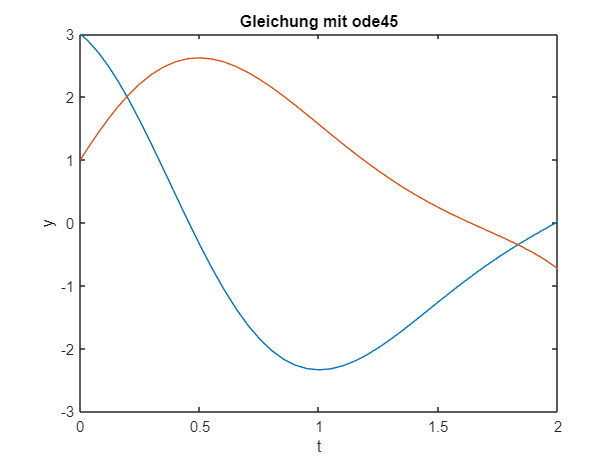

j_rb = @(t,y)[-2*t,-3;2,t.^2];

[t_rb_ode,y_rb_ode] = ode45(f_rb,tspan,ya);
[t_rb_euler,y_rb_euler] = impl_euler(f_rb,tspan,ya,n,j_rb,tol,nmax);
[t_rb_trapez,y_rb_trapez] = impl_trapez(f_rb,tspan,ya,n,j_rb,tol,nmax);
plot(t_rb_ode,y_rb_ode); 
title("Gleichung mit ode45")
xlabel("t");
ylabel("y");

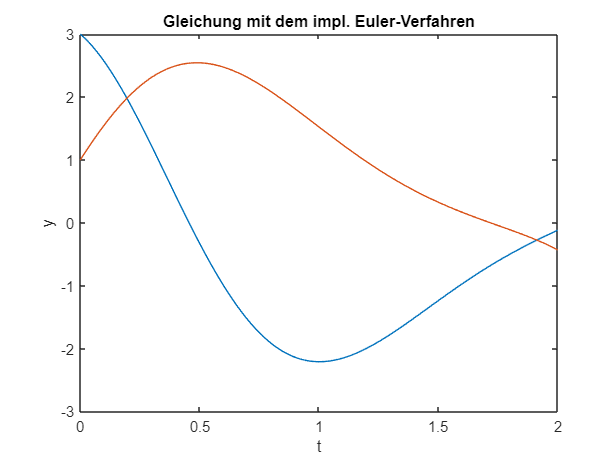

plot(t_rb_euler,y_rb_euler); 
title("Gleichung mit dem impl. Euler-Verfahren")
xlabel("t");
ylabel("y");

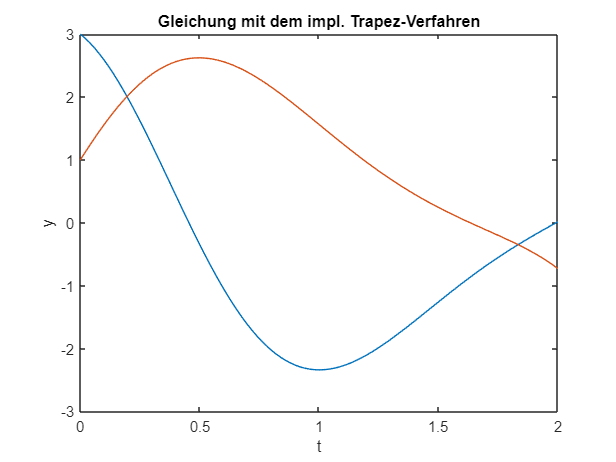

plot(t_rb_trapez,y_rb_trapez); 
title("Gleichung mit dem impl. Trapez-Verfahren")
xlabel("t");
ylabel("y");

Beim vergleichen der Graphen erkennt man, dass die implementierten Verfahren mit einem kleineneren n ungenauer werden und mit steigendem n sich dem Graphen des ode45 stark annähren. Dabei ist das implizite Euler-Verfahren am ungenausten.

### 3.2 Anwendung

In diesem Abschnitt sollen die entwickelten Löser auf das Modell der chemischen Reaktion angewandt werden. Gehen Sie dabei wie folgt vor.

#### 3.2.1 Aufstellen des Gleichungssystems

$f_{\textrm{chem}} \left(t,y\right)=\left\lbrack \begin{array}{c}
-0\ldotp 04y_1 +{10}^4 y_2 y_3 \\
0\ldotp 04y_1 -{10}^4 y_2 y_3 -3\cdot {10}^7 {y^2 }_2 \\
3\cdot {10}^7 {y^2 }_2 
\end{array}\right\rbrack$ mit den Anfangswertproblemen $y\left(0\right)=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$

#### 3.2.2  Funktionshandle f_chem()

Die Routine wurde in f_chem.m implementiert.

#### 3.2.3 Jacobi-Matrix von f_chem

% Funktion
% dy = [-0.04*y(1)+10^4*y(2)*y(3);0.04*y(1)-10^4*y(2)*y(3)-3*10^7*y(2).^2;3*10^7*y(2).^2] ;

% Ableiten
syms y1 y2 y3
J = jacobian([-0.04*y1+10^4*y2*y3;0.04*y1-10^4*y2*y3-3*10^7*y2.^2;3*10^7*y2.^2])

$$J = \left(\begin{array}{ccc} -\frac{1}{25} & 10000\,y_{3} & 10000\,y_{2}\\ \frac{1}{25} & -60000000\,y_{2}-10000\,y_{3} & -10000\,y_{2}\\ 0 & 60000000\,y_{2} & 0 \end{array}\right)$$

umgeschrieben sieht die Jacobi Matrix wie folgt aus:


$$Df_{\textrm{chem}} \left(t,y\right)=\left\lbrack \begin{array}{ccc}
-0\ldotp 04 & {10}^4 y_3  & {10}^4 y_2 \\
0\ldotp 04 & -{10}^4 y_3 -{6\cdot \;10}^7 y_2  & -{10}^4 y_2 \\
0 & 6\cdot {10}^7 y_2  & 0
\end{array}\right\rbrack$$


#### 3.2.4 Funktionshandle f_chem_jac()

Die Routine wurde in f_chem_jac.m implementiert.

#### 3.2.5 Lösen des AWP mit verschiedenen Verfahren

**Explizit Euler:**

y0=[1;0;0];
tspan = [0;1];      
tol=10e-6;
nmax=100;
n=100000;

nEuler4=10^3;
absFehlerEuler4 = max_abs_fehler_calc_n(@(n) expl_euler(@f_chem,tspan,y0,n),nEuler4)

absFehlerEuler4 = 4.8552e-04

nEuler6=1500;
absFehlerEuler6 = max_abs_fehler_calc_n(@(n) expl_euler(@f_chem,tspan,y0,n),nEuler6)

absFehlerEuler6 = 2.6025e-06

**Mittelpunktverfahren**:

nMitte4 =  600;
absFehlerMittelpunkt4 = max_abs_fehler_calc_n(@(n) mittelpunkt(@f_chem,tspan,y0,n),nMitte4)

absFehlerMittelpunkt4 = 1.3029e-04

nMitte6 = 650;
absFehlerMittelpunkt6 = max_abs_fehler_calc_n(@(n) mittelpunkt(@f_chem,tspan,y0,n),nMitte6)

absFehlerMittelpunkt6 = 4.5626e-05

**Impl. Euler-Verfahren:**

nImplEuler4 = 20;
absFehlerimplEuler = max_abs_fehler_calc_n(@(n)impl_euler(@f_chem,tspan,y0,n,@f_chem_jac,tol,nmax),nImplEuler4)

absFehlerimplEuler = 1.9243e-04

nImplEuler6 = 100;
absFehlerimplEuler6 = max_abs_fehler_calc_n(@(n)impl_euler(@f_chem,tspan,y0,n,@f_chem_jac,tol,nmax),nImplEuler6)

absFehlerimplEuler6 = 3.8915e-05

**Impl.Trapez-Verfahren:**

nImpltrapez4 = 10;
absFehlerimplTrapez = max_abs_fehler_calc_n(@(n)impl_trapez(@f_chem,tspan,y0,n,@f_chem_jac,tol,nmax),nImpltrapez4)

absFehlerimplTrapez = 7.9922e-04

nImpltrapez6 = 50;
absFehlerimplTrapez6 = max_abs_fehler_calc_n(@(n)impl_trapez(@f_chem,tspan,y0,n,@f_chem_jac,tol,nmax),nImpltrapez6)

absFehlerimplTrapez6 = 1.6038e-05

**Tabelarische Auswertung:**

AWPmit={'Expl.Euler';'Mittelpunkt';'Impl.Euler';'Impl.Trapez'};
nFehler10eminus4={nEuler4;nMitte4;nImplEuler4;nImpltrapez4};
nFehler10eminus6={nEuler6;nMitte6;nImplEuler6;nImpltrapez6};
Fehler10eminus4={absFehlerEuler4;absFehlerMittelpunkt4;absFehlerimplEuler;absFehlerimplTrapez};
Fehler10eminus6={absFehlerEuler6;absFehlerMittelpunkt6;absFehlerimplEuler6;absFehlerimplTrapez6};
tab = table(AWPmit,nFehler10eminus4,Fehler10eminus4,nFehler10eminus6,Fehler10eminus6)

tab = 4×5 table
        AWPmit         nFehler10eminus4    Fehler10eminus4    nFehler10eminus6    Fehler10eminus6
    _______________    ________________    _______________    ________________    _______________

    {'Expl.Euler' }        {[1000]}        {[4.8552e-04]}         {[1500]}        {[2.6025e-06]} 
    {'Mittelpunkt'}        {[ 600]}        {[1.3029e-04]}         {[ 650]}        {[4.5626e-05]} 
    {'Impl.Euler' }        {[  20]}        {[1.9243e-04]}         {[ 100]}        {[3.8915e-05]} 
    {'Impl.Trapez'}        {[  10]}        {[7.9922e-04]}         {[  50]}        {[1.6038e-05]} 


#### **3.2.6 Auswertung**

Die Auswertung in 3.2.5 zeigt, dass bei den expliziten-Verfahren die Mittelpunktsregel mit einem kleineren n auf den selben Fehler ${10}^{-4}$ kommt als das explizite Euler-verfahren. Die impliziten Verfahren hingegen schneiden im Allgemeinen besser als die Expliziten Verfahren ab. Hierbei ist zu sehen, dass das Impl Trapez-Verfahren aufgrund des kleineren n bessere Ergebnisse mit weniger Rechenaufwand liefert. Aus den Ergebnissen kann folgendes Ranking erstellt werden.

Verfahren={'Impl.Trapez';'Impl.Euler';'Mittelpunkt';'Expl.Euler'};
tabRanking=table(Verfahren)

tabRanking = 4×1 table
       Verfahren   
    _______________

    {'Impl.Trapez'}
    {'Impl.Euler' }
    {'Mittelpunkt'}
    {'Expl.Euler' }


## **4 Zeitaufgelöste Simulation**

In diesem Abschnitt werden die entwickelten Methode kombiniert, um die ursprüngliche Gleichung (Aufgabenblatt 1) mit  gelöst werden.


$$u\left(t,z_i \right)=D{u^{\prime } }^{\prime } \left(t,z_i \right)-\left(k_1 +k_2 N_D \right)u\left(t,z_i \right)-k_2 u^2 \left(t,z_i \right)+s\left(t,z_i \right)$$


Die Randebedingungen aus (Aufgabenblatt 3) lauten:


$$Du^{\prime } \left(0\right)=S_L u\left(0\right),\;Du^{\prime } \left(d\right)=-S_R u\left(d\right)$$


#### 4.1 Aufstellen von F(t,u)

In dieser Aufgabe werden wir die Gleichung $u^{\prime } =F\left(t,u\right)$aufstellen, indem wir genauso wie in der Aufgabe 2.2 vorgehen. Zuerst

Gegeben aus 2.2.1:


$$u^{\prime } =\frac{u_{i+1} -u_{i-1} }{2h}$$



$${u^{\prime } }^{\prime } =\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }$$


Jetzt werden die Ableitungen jeweils in die Gleichungen und den Randbedingungen eingesetzt.

**Gleichung**:

 $u\left(t\right)=D\frac{u_{i+1} \left(t\right)-{2u}_i \left(t\right)+u_{i-1} \left(t\right)}{h^2 }-\left(k_1 +k_2 N_D \right)u\left(t\right)-k_2 u^2 \left(t\right)+s_i \left(t,z_i \right)$ mit $k=k_1 +k_2 \textrm{ND}$.

**Randbedingungen:**

$D\cdot \frac{u_1 -u_{-1} }{2h}=S_L u\left(0\right)\to u_{-1} =u_1 -\frac{S_L \cdot 2h}{D}u_0 \;\;$ und $D\cdot \frac{u_{N+1} -u_{N-1} }{2h}=S_R u\left(d\right)\to u_{N+1} =-\frac{S_R \cdot 2h}{D}\cdot u_N +u_{N-1}$

Im Anschluss werden die Randbedingungen in die Gleichung für $i=0$ und $i=N\;$eingesetzt.


$$\begin{array}{l}
u^{\prime } \left(t,z_i \right)=D\frac{u_{i+1} \left(t\right)-{2u}_i \left(t\right)+u_{i-1} \left(t\right)}{h^2 }-ku_i \left(t\right)-k_2 {u_i }^2 \left(t\right)+s_i \left(t,z\right)\\
i=0\\
u^{\prime } \left(t{,z}_i \right)=D\frac{u_1 \left(t\right)-{2u}_0 \left(t\right)+u_{-1} \left(t\right)}{h^2 }-ku_0 \left(t\right)-k_2 {u_0 }^2 \left(t\right)+s_0 \left(t,z\right)\\
u^{\prime } \left(t{,z}_i \right)=D\frac{u_1 -{2u}_0 +u_1 -\frac{S_L \cdot 2h}{D}u_0 }{h^2 }-ku_0 -k_2 {u_0 }^2 +s_0 \left(z\right)\\
u^{\prime } \left(t{,z}_i \right)=D\frac{2u_1 -{2u}_0 -\frac{S_L \cdot 2h}{D}u_0 }{h^2 }-ku_0 -k_2 {u_0 }^2 +s_0 \left(z\right)\\
u^{\prime } \left(t{,z}_i \right)=\frac{2{\textrm{Du}}_1 }{h^2 }-\frac{2{\textrm{Du}}_0 }{h^2 }-\frac{D\cdot S_L 2{\textrm{hu}}_0 }{D\cdot h^2 }-ku_0 -k_2 {u_0 }^2 +s_0 \left(z\right)\\
\textrm{kürzen}\to \\
u^{\prime } \left(t{,z}_i \right)=\frac{2{\textrm{Du}}_1 }{h^2 }-\frac{2{\textrm{Du}}_0 }{h^2 }-\frac{S_L 2u_0 }{h}-ku_0 -k_2 {u_0 }^2 +s_0 \left(z\right)\\
\textrm{zusammenfassen}\to \\
\underline{\underline{\;u^{\prime } \left(t{,z}_i \right)=u_0 \left(t\right)\left(-\frac{2D}{h^2 }-\frac{{2S}_L }{h}\;-k-k_2 u_0 \left(t\right)\right)+u_1 \left(t\right)\left(\frac{2D}{h^2 }\right)+s_0 \left(t,z_0 \right)\;\textrm{für}\;i=0} } 
\end{array}$$



$$\begin{array}{l}
i=N\\
u^{\prime } \left(t{,z}_i \right)=D\frac{u_{N+1} \left(t\right)-{2u}_N \left(t\right)+u_{N-1} \left(t\right)}{h^2 }-ku_N \left(t\right)-k_2 {u_N }^2 \left(t\right)+s_N \left(z_N \right)\\
u^{\prime } \left(t{,z}_i \right)=D\frac{u_{N-1} -\frac{\;S_R \cdot 2h}{D}\cdot u_N -{2u}_N \left(t\right)+u_{N-1} \left(t\right)}{h^2 }-ku_N \left(t\right)-k_2 {u_N }^2 \left(t\right)+s_N \left(z_N \right)\\
\underline{\underline{u^{\prime } \left(t{,z}_i \right)=u_N \left(t\right)\left(-\frac{\;2S_R }{h}-\frac{\;2D}{h^2 }-k-k_2 u_N \left(t\right)\right)+u_{N-1} \left(t\right)\left(\frac{2D}{h^2 }\right)+s_0 \left(t,z_N \right)\;\textrm{für}\;i=N} } 
\end{array}$$


Jetzt sind wir in der Lage unsere Gleichung $u^{\prime } =F\left(t,u\right)$ aufzustellen.


$$F\left(t,u\right)=\left\lbrack \begin{array}{c}
u_0 \left(t\right)\left(-\frac{2D}{h^2 }-\frac{{2S}_L }{h}\;-k-k_2 u_0 \left(t\right)\right)+u_1 \left(t\right)\left(\frac{2D}{h^2 }\right)+s_0 \left(t,z_0 \right)\;\\
D\frac{u_2 \left(t\right)-{2u}_1 \left(t\right)+u_1 \left(t\right)}{h^2 }-ku_1 \left(t\right)-k_2 {u_1 }^2 \left(t\right)+s_1 \left(t,z\right)\\
\cdots \\
u_N \left(t\right)\left(-\frac{\;2S_R }{h}-\frac{\;2D}{h^2 }-k-k_2 u_N \left(t\right)\right)+u_{N-1} \left(t\right)\left(\frac{2D}{h^2 }\right)+s_0 \left(t,z_N \right)
\end{array}\right\rbrack$$


#### 4.2 Routinen fd_lin und fd_lin_jac

Die Funktionen wurden in fd_lin und in fd_lin_jac implentiert.

#### 4.3 - 4.4 Simulation des Systems mit der impliziten Trapezregel

Im Folgenden wird die implizite Trapezregel simuliert für:


$$s\left(t,z\right)=S_0 \cdot e^{-\frac{\;t^2 }{2\cdot 0\ldotp {01}^2 }} \cdot e^{-\alpha \;z} \;\;\textrm{mit}\;S_0 ={10}^4 ,{10}^5 ,{10}^6 \;\frac{1}{\mu m^3 \mu s\;}\;\textrm{und}$$
 
$$\textrm{tspan}=\left\lbrack -0\ldotp 05,2\right\rbrack \mu s$$


Bevor die Simulation mit der Trapezregel ausgeführt wurde, habe ich die Simulation zur Prüfung, zuerst mit ode23s ausgeführt. Diese ist ähnlich zu dem ode45, jedoch eignet sie sich besser für steife Differentialgleichungen und ist ein Verfahren 3.Ordnung mit Schätzung 2.Ordnung. Sie benötigt weniger Schritte als der ode45 und ist somit bei steifen Differentilagleichungen effizienter.

Rechnung:

global s0;
s0= 10^4

s0 = 10000

tspan=[-0.05,0.2];
tol=1e-6;
nmax=10;
nOrt=100;
nZeit=100;
ya=zeros(nOrt+1,1);
z=linspace(0,0.3,nOrt+1);
@fd_4

ans = function_handle with value:
    @fd_4


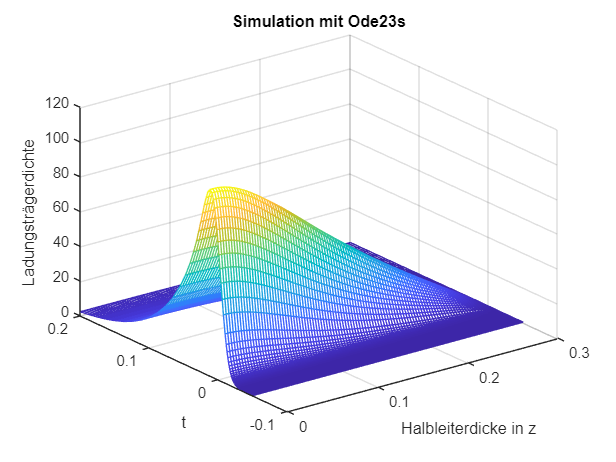

[t,y]=ode23s(@fd_4,tspan,ya);
mesh(z,t,y);
title('Simulation mit Ode23s')
xlabel('Halbleiterdicke in z')
ylabel('t')
zlabel('Ladungsträgerdichte')

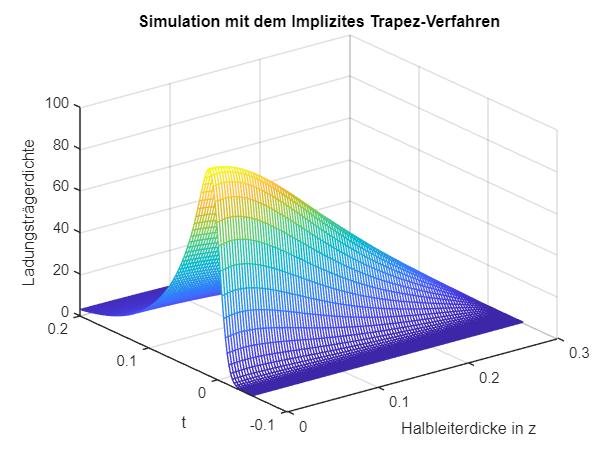

[symTrapezT,symTrapezY]=impl_trapez(@fd_4,tspan,ya,nZeit,@fd_4_jac, tol,nmax);
mesh(z,symTrapezT,symTrapezY);
title('Simulation mit dem Implizites Trapez-Verfahren')
xlabel('Halbleiterdicke in z')
ylabel('t')
zlabel('Ladungsträgerdichte')